%% Contour points (oriented correctly) and mesh size parameters
Lx = 60e-3;
Lx_outer = 20e-3;
Ly = 45e-3;
rAperture1 = 3e-3;
rAperture2 = 1.5e-3;
rAperture3 = 1e-3;
d = 34e-3;
Lx_outer2 = 120e-3;


isAxisymmetric = 1;


N_field = 6;
N_geom = 2;
N_quad = N_field + isAxisymmetric; % there is a reason for this

%p0 = [0,0,0,0,0,0,0,0]';
s = 2.1e-3; % mesh scale
ratio = 0.3;
geom2d = ParameterizedGeometry2D();
% geom2d.addContour(@(p) [-Lx, 0, Lx, Lx, 0, -Lx], @(p) [0, 0, 0, Ly, Ly, Ly], s*[0.5, 4, 0.5, 4, 4, 4], 1, 1:6);
% geom2d.addContour(@(p) [-Lx+1e-3, -Lx+2e-3, -Lx+2e-3, -Lx+1e-3] + p([1 2 2 1])', @(p) [rAperture2, rAperture2, Ly-d, Ly-d] + p([3 3 4 4])', s*0.5, 2, 1:4);
% geom2d.addContour(@(p) [-Lx+3e-3, -Lx+4e-3, -Lx+4e-3, -Lx+3e-3] + p([5 6 6 5])', @(p) [rAperture2, rAperture2, Ly-d, Ly-d] + p([7 7 8 8])', s*0.5, 3, 1:4);
% geom2d.addContour(@(p) [Lx-2e-3, Lx-1e-3, Lx-1e-3, Lx-2e-3] + p([9 10 10 9])', @(p) [rAperture3, rAperture3, Ly-d, Ly-d] + p([11 11 12 12])', s*0.5, 4, 1:4);
% geom2d.addContour(@(p) [Lx-5e-3, Lx-4e-3, Lx-4e-3, Lx-5e-3] + p([13 14 14 13])', @(p) [rAperture3, rAperture3, Ly-d, Ly-d] + p([15 15 16 16])', s*0.5, 5, 1:4);
% 
% geom2d.addContour(@(p) [-Lx, 0, Lx, Lx, 0, -Lx], @(p) [0, 0, 0, Ly, Ly, Ly], s*[0.5, 4, 0.5, 4, 4, 4], 1, 1:6);
% geom2d.addContour(@(p) [-Lx+2e-3, -Lx+3e-3, -Lx+3e-3, -Lx+2e-3], @(p) [rAperture1, rAperture1, Ly-d, Ly-d], s*0.5, 2, 1:4);
% geom2d.addContour(@(p) [-Lx+5e-3, -Lx+6e-3, -Lx+6e-3, -Lx+5e-3], @(p) [rAperture1, rAperture1, Ly-d, Ly-d], s*0.5, 3, 1:4);
% geom2d.addContour(@(p) [-Lx+10e-3, -Lx+11e-3, -Lx+11e-3, -Lx+10e-3], @(p) [rAperture1, rAperture1, Ly-d, Ly-d], s*0.5, 4, 1:4);
% geom2d.addContour(@(p) [-Lx+13e-3, -Lx+14e-3, -Lx+14e-3, -Lx+13e-3], @(p) [rAperture1, rAperture1, Ly-d, Ly-d], s*0.5, 5, 1:4);
l2 = 5e-3;
l1 = 2e-3;
l3 = 2e-3;
Vb = 29e3;
D1 = 3e-3;
L1 = 5e-3;
e_d = 7.5e-3;
Wd = 43e-3;
Wd2 = 164e-3;

        geom2d.addContour(@(p) [-Lx-Lx_outer-Lx_outer2, -Lx+e_d+Wd, 0,-Lx+e_d+Wd+l1+L1+l2+L1+l3, Lx+Lx_outer, Lx+Lx_outer, 0, -Lx-Lx_outer-Lx_outer2], @(p) [0, 0, 0, 0, 0, Ly, Ly, Ly], s*[5, ratio, ratio, ratio, 5, 8, 8, 8], 1, 1:8);
        geom2d.addContour(@(p) [-Lx+e_d+Wd, -Lx+e_d+Wd+l1, -Lx+e_d+Wd+l1, -Lx+e_d+Wd], @(p) [D1, D1, Ly-d, Ly-d], s*ratio*[1, 1, 2, 2], 2, 1:4);
        geom2d.addContour(@(p) [-Lx+e_d+Wd+l1+L1, -Lx+e_d+Wd+l1+L1+l2, -Lx+e_d+Wd+l1+L1+l2, -Lx+e_d+Wd+l1+L1], @(p) [D1, D1, Ly-d, Ly-d], s*ratio*[1, 1, 2, 2], 3, 1:4);
        geom2d.addContour(@(p) [-Lx+e_d+Wd+l1+L1+l2+L1, -Lx+e_d+Wd+l1+L1+l2+L1+l3, -Lx+e_d+Wd+l1+L1+l2+L1+l3, -Lx+e_d+Wd+l1+L1+l2+L1], @(p) [D1, D1, Ly-d, Ly-d], s*ratio*[1, 1, 2, 2], 4, 1:4);


fem = FEMInterface(geom2d, N_field, N_geom, N_quad, isAxisymmetric);
fem.setNeumann(1, @(p,x,y) 0.0);
% % fem.setDirichlet(2, @(p,x,y) 0.0 + x_old(1) + p(17));
% % fem.setDirichlet(3, @(p,x,y) 1.0 + x_old(2) + p(18));
% % fem.setDirichlet(4, @(p,x,y) 1.0 + x_old(3) + p(19));
% % fem.setDirichlet(5, @(p,x,y) 0.0 + x_old(4) + p(20));
fem.setDirichlet(2, @(p,x,y) 0 + p(1));
fem.setDirichlet(3, @(p,x,y) Vb + p(2));
fem.setDirichlet(4, @(p,x,y) 0 + p(3));
%fem.setDirichlet(5, @(p,x,y) 0.0 + p(4));

fem.setFreeCharge(@(p,x,y) 0.0);




p = [0,0,0]';


x0 = zeros(1,4)';
[~] = fem.instantiateProblem(p);

[femProblem, dDirichlet_dp, dnx_dp, dny_dp] = fem.adjustProblem(p);

xyGeomNodes = femProblem.poi.tnMesh.xyNodes;

measBox = [-Lx-Lx_outer2-Lx_outer*0.5, 0, 55e-3, 0.7e-3]; %[-0.5, -0.5, 0.5, 0.5];

fprintf('Forward solution... ');

Forward solution... 

xCoarse = linspace(-Lx-Lx_outer2-Lx_outer, Lx+Lx_outer, 200);
yCoarse = linspace(0, Ly, 200);
femProblem.solveCartesian(measBox(1:2), measBox(3:4), [200 80]);



%Nx_vec = [50 100 150 200 300 400 800 1600 3200];
%Ny_vec = [20 40 60 80 120 160 320 640 1280]*5;
 Nx_vec = 350;
 Ny_vec = 170;
 
 

max_i = length(Nx_vec);

u = femProblem.poi.tnMesh.rasterizeField(femProblem.u, xCoarse, yCoarse);
measNxy = [Nx_vec(i), Ny_vec(i)];

u_cartesian3 = femProblem.poi.tnMesh.rasterizeField(femProblem.u,...
       linspace(measBox(1),measBox(3),measNxy(1)), ...
       linspace(measBox(2),measBox(4),measNxy(2)));

Iteration 1

Partcle 1 


Elapsed time is 2.092825 seconds.


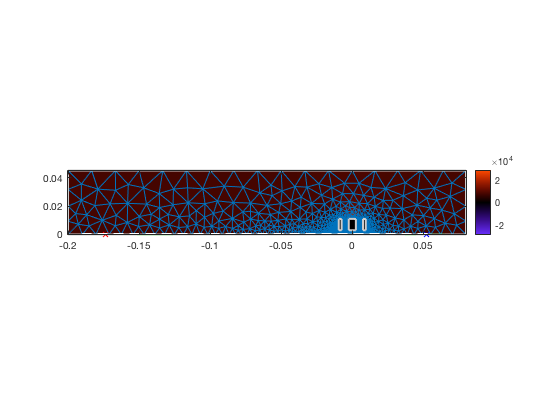

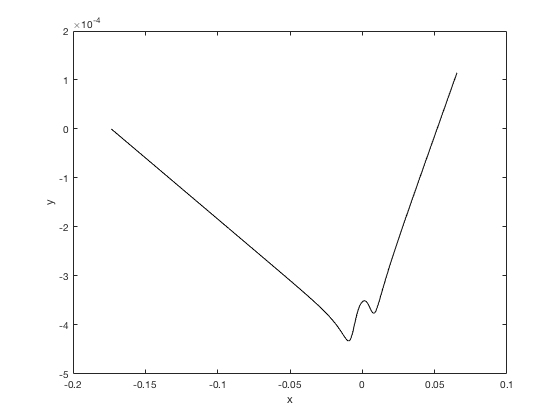

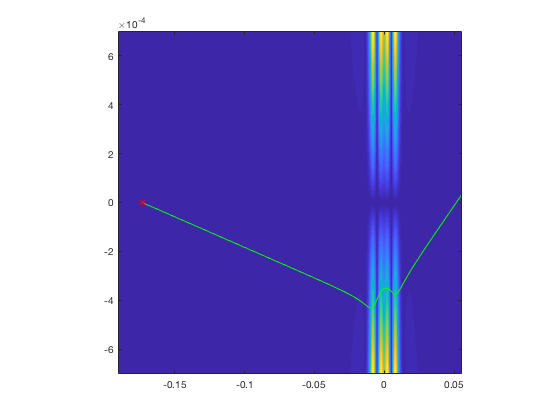

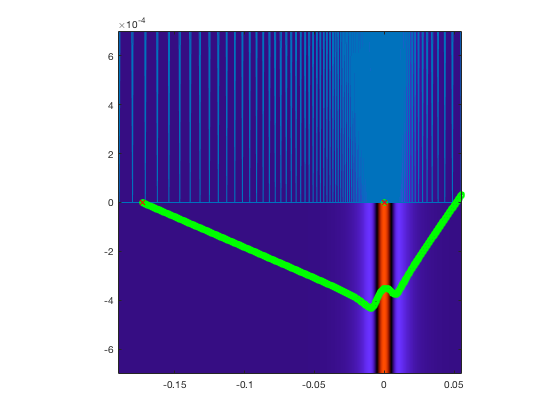


xv_cell = cell(max_i);

for i = 1:max_i
    
    fprintf('Iteration %i', i)
    fprintf('\n')

    measNxy = [Nx_vec(i), Ny_vec(i)];

   u_cartesian = femProblem.poi.tnMesh.rasterizeField(femProblem.u,...
       linspace(measBox(1),measBox(3),measNxy(1)), ...
       linspace(measBox(2),measBox(4),measNxy(2)));
    
    elementary_charge   = 1.60217662e-19;
        
    Nt = 1500;


        Nx          = measNxy(1);
        Ny          = measNxy(2);
        Nz          = 2;

     

        uu = zeros(Nx,Ny,Nz);
        uu(:,:,1) = u_cartesian;
        uu(:,:,2) = u_cartesian;


        E_center = 30*1e3*elementary_charge;
        ion_mass = 5.1477e-26;
        delta_E = 10*elementary_charge; 


        Nr = 100;
        
        E_center = 30*1e3*elementary_charge;
ion_mass = 5.1477e-26;
v_center = sqrt(2*E_center / ion_mass);
delta_E = 10*elementary_charge; 
v_spread = sqrt(2*delta_E / ion_mass);

angle = linspace(-2.5e-3,2.5e-3,Nr);


y_radius = 0;
velocities = v_center;

x_pos = -173.5e-3;

[xx, yy, angles, vv] = ndgrid(x_pos, y_radius, angle, velocities);
angles = angles(:);
vv = vv(:);
xv0 = [xx(:)'; yy(:)'; zeros(length(xx(:)),1)'; (vv.*cos(angles))'; (vv.*sin(angles))'; zeros(length(xx(:)),1)'];

       % y_vec = linspace(0e-6,50e-6,Nr);%linspace(1e-4,10e-6,Nr);%linspace(0.5e-6,5e-6,Nr);
      %  xv0 = [x_pos*ones(1,Nr);y_vec ;zeros(1,Nr); v_center*ones(1,Nr); zeros(1,Nr); zeros(1,Nr)];
        x_grid = linspace(measBox(1),measBox(3),measNxy(1));
        y_grid = linspace(measBox(2),measBox(4),measNxy(2));
        z_grid = [-2, 0];

        x_p = 52.5e-3;
        y_p  = 0;
        z_p  = 0;
        vx_p = 1e-3;
        vy_p = 0;
        vz_p = 0;

        obj_weights = [1, 1, 0, 0, 0, 0];

        U = [uu(:,end:-1:2,:) uu(:,:,:)];

        r_grid = [-y_grid(end:-1:2) y_grid];

        d_x = x_grid(2) - x_grid(1);
        d_r = y_grid(2) - y_grid(1);
        d_z = z_grid(2) - z_grid(1);


        E_x         = -centeredDiff(U, 1) / d_x;
        E_r         = -centeredDiff(U, 2) / d_r;
        E_z         = -centeredDiff(U, 3) / d_z;
 
        end_time = (120e-3 ./ (v_center))*2.5;
        end_time = end_time - 0.2*end_time;
        electron_mass       = 1.6605e-27;

        n_charges = -1;
        n_masses = ion_mass/electron_mass;
        
        accelFunc = accelerationFunction( x_grid, r_grid, z_grid, ...
            n_charges, n_masses);

        ts = linspace(0, end_time, Nt);
        nParticle = size(xv0,2);
        xv_matrix = zeros(6*Nt,nParticle);
        
        [ix_x, ix_y, ix_z, ~] =...
            get_Index3D(Nt);
        for zz = 1:1
            %xv0(:,zz)
            tic
            fprintf('Partcle %i \n', zz)
            [xv_matrix(:,zz), accel] = velocityVerlet3D(ts, xv0(:,zz), accelFunc(E_x, E_r, E_z));
            %xv_matrix(ix_y(1),zz)
            xv = xv_matrix(:,zz);
            toc
        end
        xv_cell{i} = xv;
        
        figure(100); clf

        imagesc_centered(xCoarse, yCoarse, u'); axis xy image; colorbar
        ax = axis;
        colormap orangecrush
        hold on
        femProblem.poi.tnMesh.plotMesh();

        geometry = fem.instantiatedGeom.geometry;
        plot([geometry.vertices(geometry.lines(:,1),1), geometry.vertices(geometry.lines(:,2),1)]', ...
            [geometry.vertices(geometry.lines(:,1),2), geometry.vertices(geometry.lines(:,2),2)]', 'color', [0.8 0.8 0.8], 'linewidth', 2)

        [ix_x, ix_y, ix_z, ~] =...
            get_Index3D(Nt);
        for ii = 1:size(xv,2)
            plot(xv(ix_x,ii),xv(ix_y,ii),'g', 'LineWidth', 1)
            plot(xv(ix_x(1),ii),xv(ix_y(1),ii),'rx')
        end
        plot(x_p,y_p,'bx')



        plot(measBox([1,3,3,1,1]), measBox([2,2,4,4,2]), 'w--');
        axis(ax)
        
        figure(110)
        clf
        plot(xv(ix_x,1),xv(ix_y,1),'k','LineWidth',1)
        xlabel('x')
        ylabel('y')  
        
        figure(111+i)
        clf
        imagesc(x_grid,r_grid,abs(E_r(:,:,2))')
        axis xy
        axis square
        hold on 
        for ii = 1:size(xv,2)
            plot(xv_matrix(ix_x,ii),xv_matrix(ix_y,ii),'g', 'LineWidth', 1)
            plot(xv_matrix(ix_x(1),ii),xv_matrix(ix_y(1),ii),'rx')
        end
        
        figure(1510+i)
        clf
        imagesc(x_grid,r_grid,U(:,:,2)')
        axis xy
        axis square
        hold on 
        femProblem.poi.tnMesh.plotMesh();

        for ii = 1:size(xv_matrix,2)
            plot(xv_matrix(ix_x,ii),xv_matrix(ix_y,ii),'o','Color','g', 'LineWidth', 1)
            plot(xv_matrix(ix_x(1),ii),xv_matrix(ix_y(1),ii),'rx')
        end
        colormap orangecrush
end